clear
load 20210305-RC_Chirp40v150kHz_T2s.mat
A1=A;
B1=B;
N=Length;
dt=Tinterval

dt = 1.0000e-06

fs=1/dt

fs = 1.0000e+06

t=(0:N-1)*dt;
df=fs/N;
f=(0:df:fs-df);
load 20220401-RLC_Chirp1v300kHz_T2s.mat
A2=A;
B2=B;


R1=47;
C1=2.2e-6;

R2=220;
C2=4.7e-6;
L2=1e-3;

num1=1/(R1*C1)

num1 = 9.6712e+03

den1=[1 num1]

den1 = 1.0e+03 *

    0.0010    9.6712


sys=tf(num1,den1)


sys =
 
    9671
  --------
  s + 9671
 
Continuous-time transfer function.
Model Properties



num2=[R2/L2 0]

num2 =       220000           0


den2=[1 R2/L2 1/(C2*L2)]

den2 = 1.0e+08 *

    0.0000    0.0022    2.1277


sys2=tf(num2,den2)


sys2 =
 
          220000 s
  -------------------------
  s^2 + 220000 s + 2.128e08
 
Continuous-time transfer function.
Model Properties


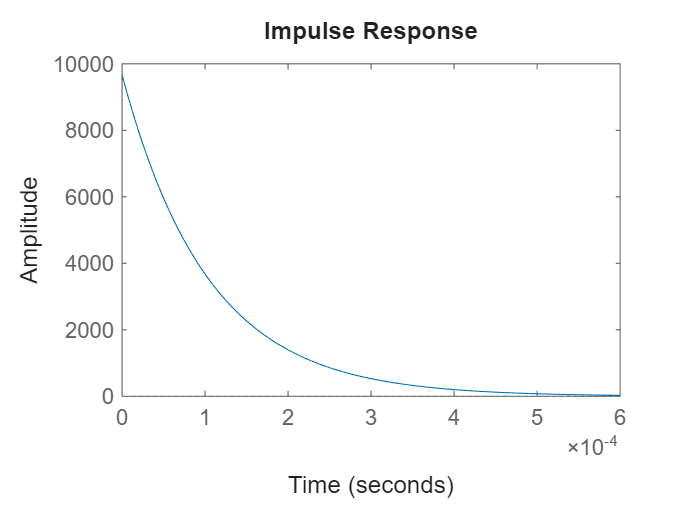

impulse(sys)

From the impulse we see that the system should be critically damped.

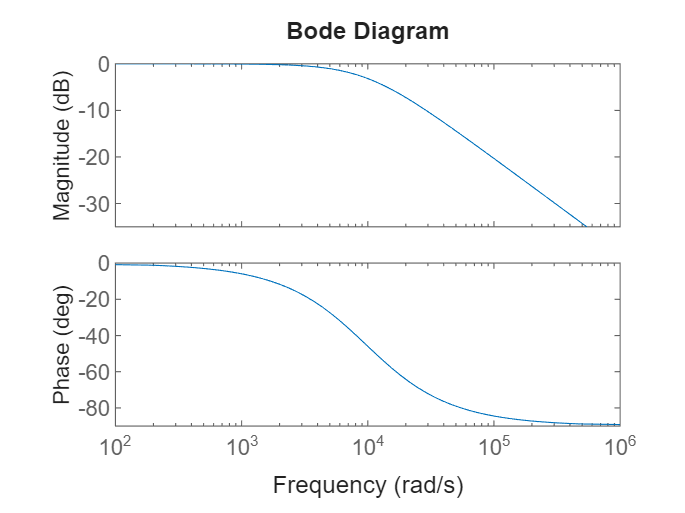

bode(sys)

-3dB threshold at 9.67e03 rad/s, so 1.5390 kHz

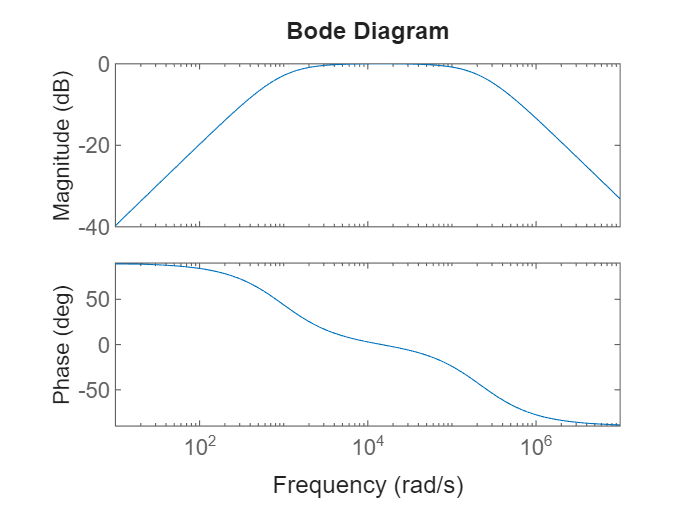

bode(sys2)

attenuation grater than -3bB between 913 rad/s and 23.3k rad/s

w1=913;
w2=2.33e05;
wr=1.46e04;
damping = (w2-w1)/(2*wr)

damping = 7.9482

Signal analysys:

A1(isnan(A1)) = 0;
B1(isnan(B)) = 0;
A2(isinf(A2)) = 0;
B2(isinf(B2)) = 0;

B – measured input signal v(t)

% plot(t,B1)
% hist(B1)
% plot(f,20*log10(abs(fft(B1))))

A – measured output signal y(t)

% plot(t,A1)
% hist(A1)
% plot(f,20*log10(abs(fft(A1))))

% plot(t,B2)
% hist(B2)
% plot(f,20*log10(abs(fft(B2))))
% plot(t,A2)
% hist(A2)
% plot(f,20*log10(abs(fft(A2))))

## Ex.1.1

Creating system response Y(w) for chirp input V(w)

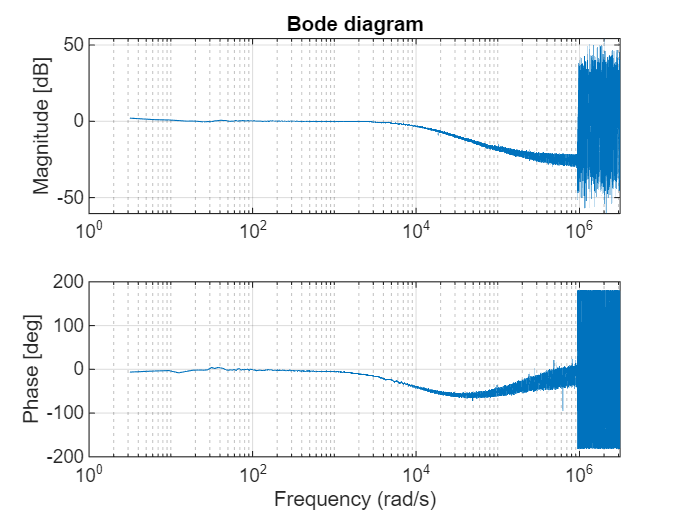

ownBode(B1,A1,fs)

This looks like a lowpass of sorts up till 940k rad/s where weird stuff happen

We see attenuation of -3dB at around 10k rad/s which is consistent with matlab bode plot of the lowpass filter

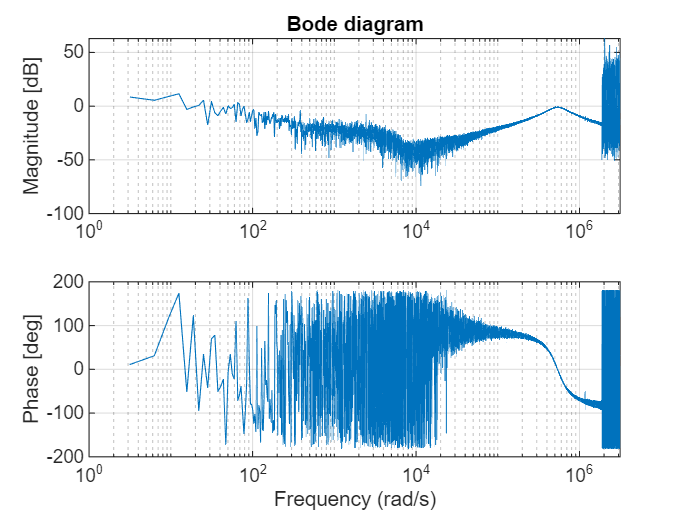

ownBode(B2,A2,fs)

We see that attenuation starts at 85 rad/s and comes back above -3dB at 42.5k rad/s. This range is far wider than the bode plot of the filter would indicate.

peak of -0.719dB at 5.479e05rad/s

w1=4.1e05

w1 = 410000

w2=7.1e05

w2 = 710000

damping2=(7.1-4.1)/(2*5.479)

damping2 = 0.2738

Here the calculated damping is significantly lower than calculated on the theoritical bode of our system

## Ex1.2. 

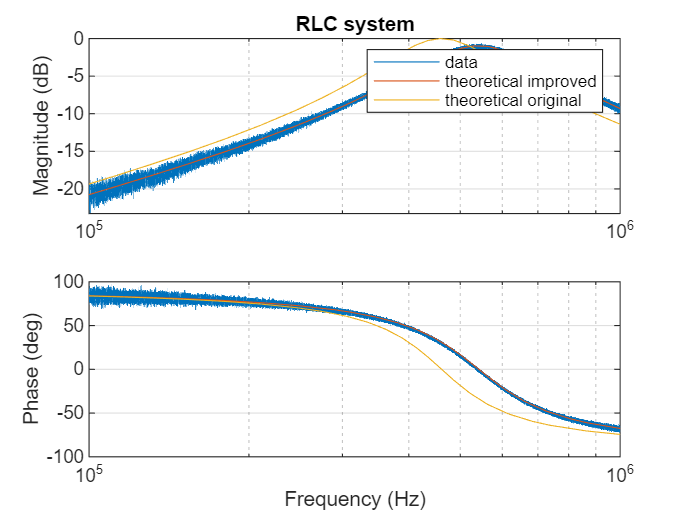

% Paramaters
R2 = 217;
C2 = 4.1e-9;
L2 = 0.83e-3;
R2L = 25;
Ind=15.4;
R2R = 220;
C2R = 4.7e-9;
L2R = 1e-3;

sys_1 = tf([(R2/L2) 0],[1 ((R2 + R2L)/L2) (1/(C2 * L2))]);
[mag1,phase1,w1]=bode(sys_1);
mag1=squeeze(mag1);
phase1=squeeze(phase1);
sys_2 = tf([(R2R/L2R) 0],[1 R2R/L2R 1/(C2R * L2R)]);
[mag2,phase2,w2]=bode(sys_2);
mag2=squeeze(mag2);
phase2=squeeze(phase2);

% Load RLC
L2=load("20220401-RLC_Chirp1v300kHz_T2s.mat");
A2=L2.A;
B2=L2.B;
A2(isnan(A2)) = 0;
B2(isnan(B2)) = 0;
A2(isinf(A2)) = 0;
B2(isinf(B2)) = 0;
fsRLC = 1/L2.Tinterval;
H_RLC_S = fft(A2)./fft(B2);
dfRLC=fsRLC/L2.Length;
freqRLC =(0:dfRLC:fsRLC-dfRLC);
phiRLC = angle(H_RLC_S);

figure
subplot(2,1,1)
semilogx(freqRLC(1:floor(L2.Length/2))*2*pi,20*log10(abs(H_RLC_S(1:floor(L2.Length/2))))), grid on, hold on
semilogx(w1, 20*log10(mag1))
semilogx(w2, 20*log10(mag2)), hold off
ylabel('Magnitude (dB)')
title('RLC system')
legend('data','theoretical improved','theoretical original')
xlim([1e5 1e6])
subplot(2,1,2)
semilogx(freqRLC(1:floor(L2.Length/2))*2*pi, phiRLC(1:floor(L2.Length/2))*180/pi), grid on, hold on
semilogx(w1, phase1)
semilogx(w2, phase2), hold off
xlabel('Frequency (Hz)')
ylabel('Phase (deg)')
xlim([1e5 1e6])

## Task 2

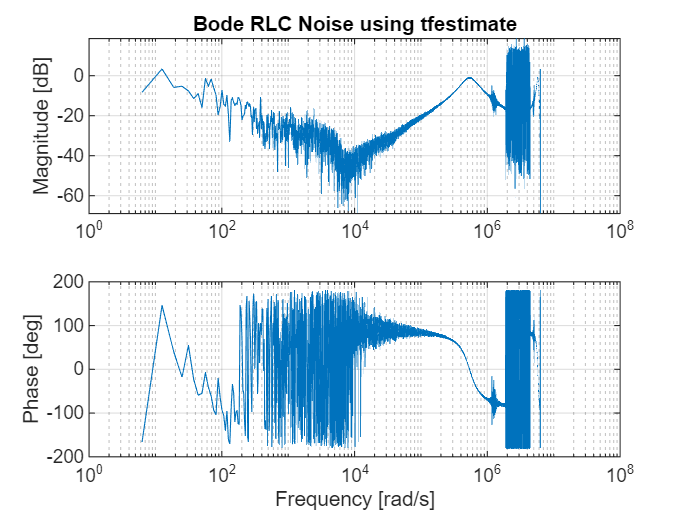

load('20220401-RLC_Chirp1v300kHz_T2s.mat')
df = 1;
dt=Tinterval;
fs=1/dt;
window = round(fs/df);
overlap = round(window / 2);
nfft = window;
[H,F]=tfestimate(B,A,window,overlap,nfft,Tinterval,'twosided');
F=F';
N=length(H);
f=2*pi*1/dt*(0:(N-1))/N;
mag_sys=abs(H);
phase_deg=rad2deg(angle(H));
figure()
subplot(2,1,1);
semilogx(f,20*log10(mag_sys)), grid on
ylabel('Magnitude [dB]')
title('Bode RLC Noise using tfestimate')
subplot(2,1,2);
semilogx(f,phase_deg), grid on
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')

## Task 3

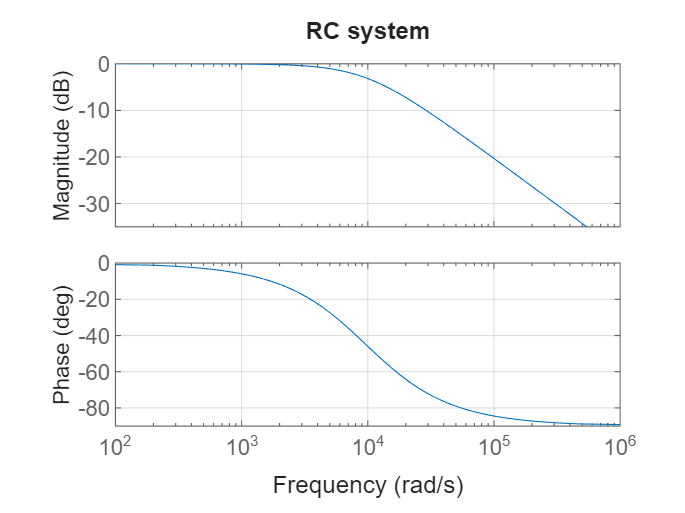

clear
R_1 = 47;
C_1 = 2.2e-6;
R2 = 217;
C2 = 4.1e-9;
L2 = 0.83e-3;
R2L = 25;
% Create systems
H_RC = tf(1/(R_1 * C_1),[1 1/(R_1 * C_1)]);
[mag1,phase1,w1]=bode(H_RC);
mag1=squeeze(mag1);
phase1=squeeze(phase1);
H_RLC = tf([(R2/L2) 0],[1 ((R2 + R2L)/L2) (1/(C2 * L2))]);
[mag2,phase2,w2]=bode(H_RLC);
mag2=squeeze(mag2);
phase2=squeeze(phase2);
% Bode plots
figure
bode(H_RC), grid on
title('RC system')

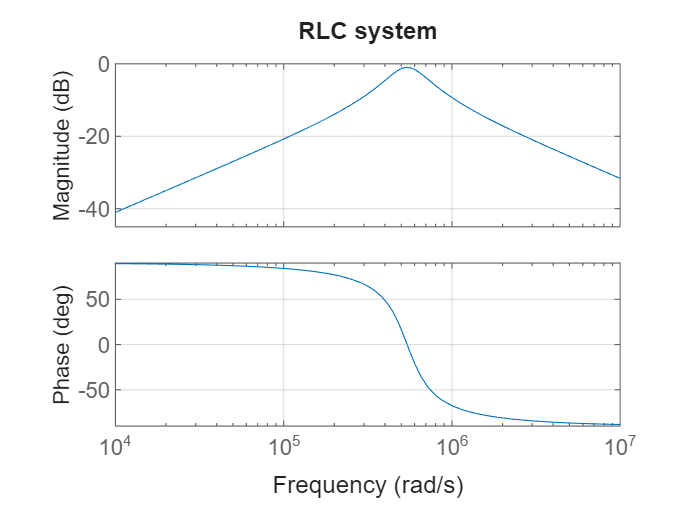

figure
bode(H_RLC), grid on
title('RLC system')

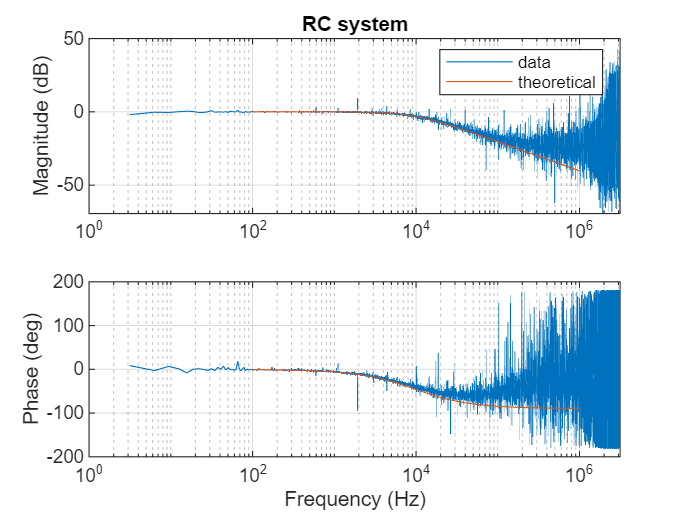

%%
% Load RC
L1=load("20210305-RC_SzumBand200kHz_T2s");
A2=L1.A;
B2=L1.B;
A2(isnan(A2)) = 0;
B2(isnan(B2)) = 0;
A2(isinf(A2)) = 0;
B2(isinf(B2)) = 0;
fsRC = 1/L1.Tinterval;
H_RC_S = fft(A2)./fft(B2);
dfRC=fsRC/L1.Length;
freqRC =(0:dfRC:fsRC-dfRC);
phiRC = angle(H_RC_S);
% Load RLC
L2=load("20220401-RLC_SzumBand500kHz_T2");
A2=L2.A;
B2=L2.B;
A2(isnan(A2)) = 0;
B2(isnan(B2)) = 0;
A2(isinf(A2)) = 0;
B2(isinf(B2)) = 0;
fsRLC = 1/L2.Tinterval;
H_RLC_S = fft(A2)./fft(B2);
dfRLC=fsRLC/L2.Length;
freqRLC =(0:dfRLC:fsRLC-dfRLC);
phiRLC = angle(H_RLC_S);
figure
subplot(2,1,1)
semilogx(freqRC(1:floor(L1.Length/2))*2*pi,20*log10(abs(H_RC_S(1:floor(L1.Length/2))))), grid on, hold on
semilogx(w1, 20*log10(mag1)), hold off
ylabel('Magnitude (dB)')
title('RC system')
legend('data','theoretical')
% xlim([40 150e3])
subplot(2,1,2)
semilogx(freqRC(1:floor(L1.Length/2))*2*pi, phiRC(1:floor(L1.Length/2))*180/pi), grid on, hold on
semilogx(w1,phase1)
xlabel('Frequency (Hz)')
% xlim([1e2 1e6])
ylabel('Phase (deg)')

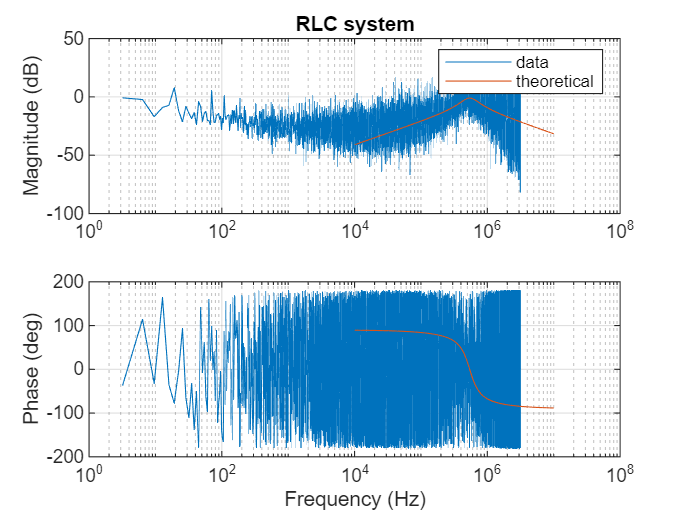

figure
subplot(2,1,1)
semilogx(freqRLC(1:floor(L2.Length/2))*2*pi,20*log10(abs(H_RLC_S(1:floor(L2.Length/2))))), grid on, hold on
semilogx(w2, 20*log10(mag2)), hold off
ylabel('Magnitude (dB)')
title('RLC system')
legend('data','theoretical')
% xlim([1e2 1e6])
subplot(2,1,2)
semilogx(freqRLC(1:floor(L2.Length/2))*2*pi, phiRLC(1:floor(L2.Length/2))*180/pi), grid on, hold on
semilogx(w2, phase2), hold off
xlabel('Frequency (Hz)')
ylabel('Phase (deg)')

% xlim([1e2 1e6])

## Task 3.2

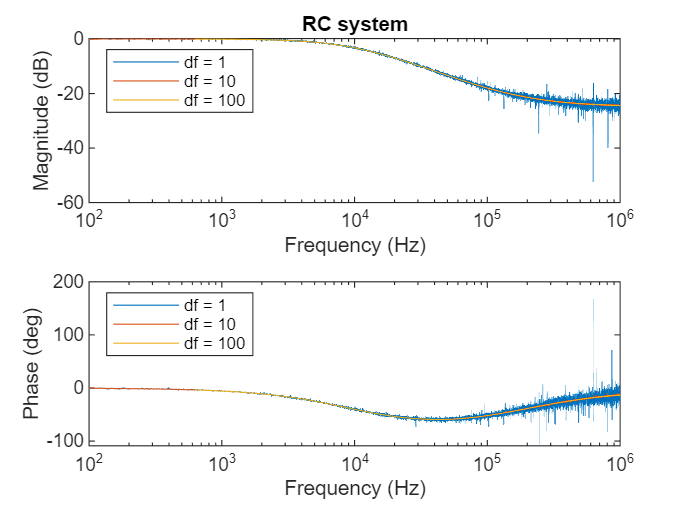

% set overlap
overlap = [];
% sampling frequency as integer
fsRC = 1e6;
fsRLC = 1e6;
% Load data for RC
load('20210305-RC_SzumBand200kHz_T2s')
A(isnan(A)) = 0;
B(isnan(B)) = 0;
A(isinf(A)) = 0;
B(isinf(B)) = 0;
% Set up for RC = 1
df = 1;
window = fsRC / df;
nfft = window;
[H_RC_Es_1,FRC_1] = tfestimate(B,A,window,overlap,nfft,fsRC,'twosided');
L1=length(H_RC_Es_1);
f1=2*pi*1/Tinterval*(0:(L1-1))/L1;
% Set up for RC = 10
df = 10;
window = fsRC / df;
nfft = window;
[H_RC_Es_10,FRC_10] = tfestimate(B,A,window,overlap,nfft,fsRC,'twosided');
L2=length(H_RC_Es_10);
f2=2*pi*1/Tinterval*(0:(L2-1))/L2;
% Set up for RC = 100
df = 100;
window = fsRC / df;
nfft = window;
[H_RC_Es_100,FRC_100] = tfestimate(B,A,window,overlap,nfft,fsRC,'twosided');
L3=length(H_RC_Es_100);
f3=2*pi*1/Tinterval*(0:(L3-1))/L3;
% Load data for RLC
load('20220401-RLC_SzumBand500kHz_T2');
A(isnan(A)) = 0;
B(isnan(B)) = 0;
A(isinf(A)) = 0;
B(isinf(B)) = 0;
% Set up for RLC = 1
df = 1;
window = fsRLC / df;
nfft = window;
[H_RLC_Es_1,FRLC_1] = tfestimate(B,A,window,overlap,nfft,fsRLC,'twosided');
L4=length(H_RLC_Es_1);
f4=2*pi*1/Tinterval*(0:(L4-1))/L4;
% Set up for RLC = 10

df = 10;
window = fsRLC / df;
nfft = window;
[H_RLC_Es_10,FRLC_10] = tfestimate(B,A,window,overlap,nfft,fsRLC,'twosided');
L5=length(H_RLC_Es_10);
f5=2*pi*1/Tinterval*(0:(L5-1))/L5;
% Set up for RLC = 100
df = 100;
window = fsRLC / df;
nfft = window;
[H_RLC_Es_100,FRLC_100] = tfestimate(B,A,window,overlap,nfft,fsRLC,'twosided');
L6=length(H_RLC_Es_100);
f6=2*pi*1/Tinterval*(0:(L6-1))/L6;
% Phases:
phiRC_1 = angle(H_RC_Es_1);
phiRC_10 = angle(H_RC_Es_10);
phiRC_100 = angle(H_RC_Es_100);
phiRLC_1 = angle(H_RLC_Es_1);
phiRLC_10 = angle(H_RLC_Es_10);
phiRLC_100 = angle(H_RLC_Es_100);
%% Plot generation:
% Plot for RC:
figure
title("RC")
subplot(2,1,1)
semilogx(f1,20*log10(abs(H_RC_Es_1)));
hold on;
semilogx(f2,20*log10(abs(H_RC_Es_10)));
semilogx(f3,20*log10(abs(H_RC_Es_100)));
hold off;
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('RC system')
legend("df = 1", "df = 10", "df = 100",'Location','northwest')
xlim([1e2 1e6])
subplot(2,1,2)
semilogx(f1, phiRC_1*180/pi);
hold on;
semilogx(f2, phiRC_10*180/pi);
semilogx(f3, phiRC_100*180/pi);
hold off;
xlabel('Frequency (Hz)')
ylabel('Phase (deg)')
legend("df = 1", "df = 10", "df = 100",'Location','northwest')
xlim([1e2 1e6])

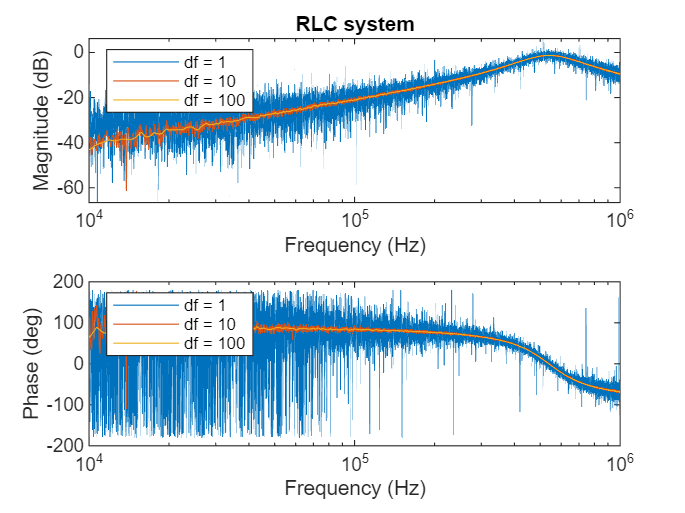

% Plot for RLC:
figure
title("RLC")
subplot(2,1,1)
semilogx(f4,20*log10(abs(H_RLC_Es_1)));
hold on;

semilogx(f5,20*log10(abs(H_RLC_Es_10)));
semilogx(f6,20*log10(abs(H_RLC_Es_100)));
hold off;
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('RLC system')
legend("df = 1", "df = 10", "df = 100",'Location','northwest')
xlim([1e4 1e6])
subplot(2,1,2)
semilogx(f4, phiRLC_1*180/pi);
hold on;
semilogx(f5, phiRLC_10*180/pi);
semilogx(f6, phiRLC_100*180/pi);
hold off;
xlabel('Frequency (Hz)')
ylabel('Phase (deg)')
legend("df = 1", "df = 10", "df = 100",'Location','northwest')
xlim([1e4 1e6])

function ownBode(x1,y1,fs)

N=length(x1);
X=fft(x1);
Y=fft(y1);
H=Y./X;
H_mag=abs(H);
df=fs/N;
f=(0:df:fs-df);
figure
title('Bode diagram')
subplot(211)
semilogx(f(1:floor(N/2))*2*pi,20*log10(H_mag(1:floor(N/2))))
title('Bode diagram')
grid on
% xlim([10e3,10e6]);
ylabel('Magnitude [dB]')
subplot(212)
H_phase=angle(H);
semilogx(f(1:floor(N/2))*2*pi,rad2deg(H_phase(1:floor(N/2))))
% xlim([10e3,10e6]);
grid on
ylabel('Phase [deg]')
xlabel('Frequency (rad/s)')
end